# 3.3 Mechatronic System

## System Values

% Inputs
m = 15;
g = -9.81;
Fg = m * g; % gravitational force
Vdc = 30; % dc-motor armature voltage
% Parameters
Ra = 0.75;      % [Ohm]
La = 10e-3;     % [H]
b1 = 200;       % [Ns/m]
b2 = 50;        % [Ns/m]
b3 = 0.25;      % [Ns/m]
J1 = 50e-2;     % [kgmˆ2]
J2 = 20e-3;     % [kgmˆ2]
k1 = 10;        % [N/m]
k2 = 250;       % [N/m]
r = 0.1;        % [m]
psi = 0.66;     % [Vs]

% State-Space Representation of the System
% state variables:
% x1 = ia
% x2 = w1
% x3 = w2
% x4 = Tk1
% x5 = Fk2
% conflict appears at the I:m element thus no state variable is introduced

Jtot = J2 + r^2*m;
a11 = -Ra/La;
a12 = -psi/La;
a21 = psi/J1;
a22 = -(b1+b3)/J1;
a23 = b1/J1;
a32 = b1/Jtot;
a33 = -(b1 + r^2*b2)/Jtot;
a34 = -1/Jtot;
a35 = -r/Jtot;
a43 = k1;
a53 = k2*r;

A = [a11 a12 0 0 0;
     a21 a22 a23 0 0;
     0 a32 a33 a34 a35;
     0 0 a43 0 0;
     0 0 a53 0 0];

b = [1/La 0; 0 0; 0 r/Jtot; 0 0; 0 0];
c = [0 0 r 0 0;
     1 0 0 0 0]; % output = x3 = w2

d = zeros(2,2);
u = [Vdc; Fg];

sys_mech = ss(A,b,c,d);


## Simulation Properties

x0 = 1;
h = 1e-6

h = 1.0000e-06

tend = 3;
t = 0:h:tend;

## Foward Euler

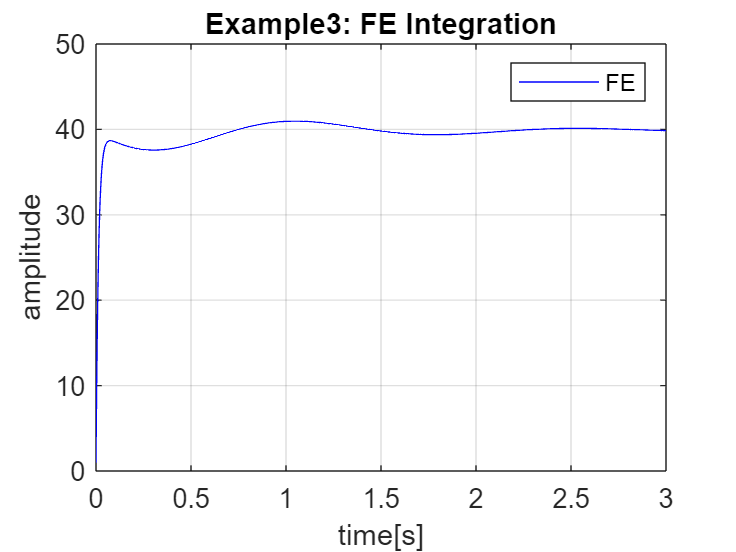

yFE3 = FE(A,b,c,d,u,h,tend,x0);

%Plotting
figure(3);
plot(t,yFE3(2,:),"blue");
title('Example3: FE Integration');
ylabel('amplitude');
xlabel('time[s]');
legend('FE');
grid on;


% lsim(sys_mech, [Vdc,Fg], t);

## Backward Euler

hBE = 1e-6

hBE = 1.0000e-06

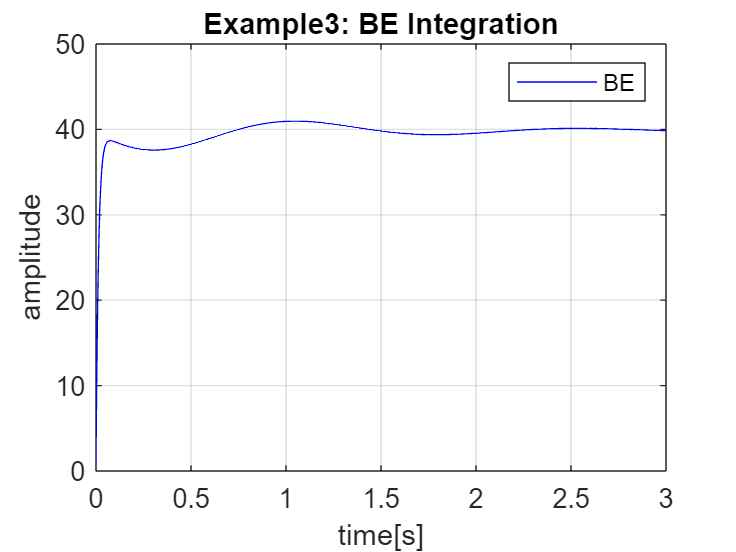

tBE = 0:hBE:tend;
yBE = BE(A,b,c,d,u,hBE,tend,x0); 

figure(4)
plot(tBE,yBE(2,:),"blue");
title('Example3: BE Integration'); grid on;
ylabel('amplitude'); xlabel('time[s]'); legend('BE');

## Runge Kuta 4.Order

hRK4 = 1000e-6

hRK4 = 1.0000e-03

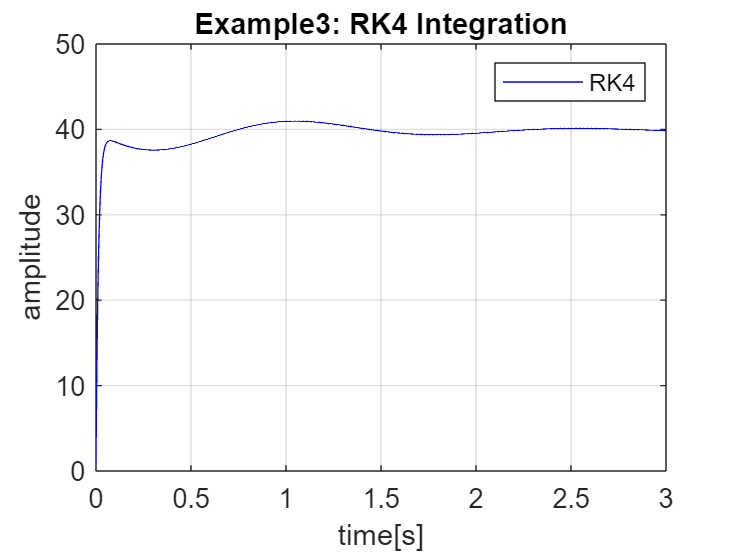

tRK4 = 0:hRK4:tend;
yRK4 = RK4(A,b,c,d,u,hRK4,tend,x0); 

figure(5)
plot(tRK4,yRK4(2,:),"blue");
title('Example3: RK4 Integration'); grid on;
ylabel('amplitude'); xlabel('time[s]'); legend('RK4');

## AB3 Solver

hAB3 = 100e-6

hAB3 = 1.0000e-04

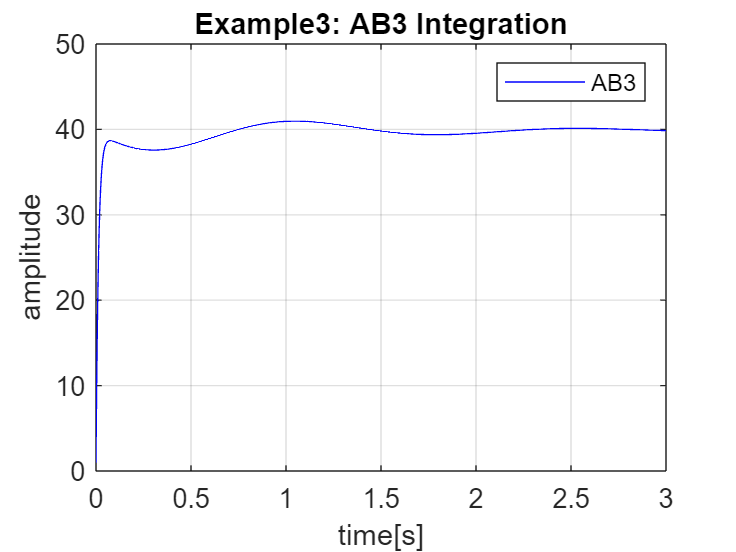

tAB3 = 0:hAB3:tend;
yAB3 = AB3(A,b,c,d,u,hAB3,tend,x0); 

plot(tAB3,yAB3(2,:),"blue");
title('Example3: AB3 Integration'); grid on;
ylabel('amplitude'); xlabel('time[s]'); legend('AB3');

## BDF3 Solver

hBDF3 = 0.01

hBDF3 = 0.0100

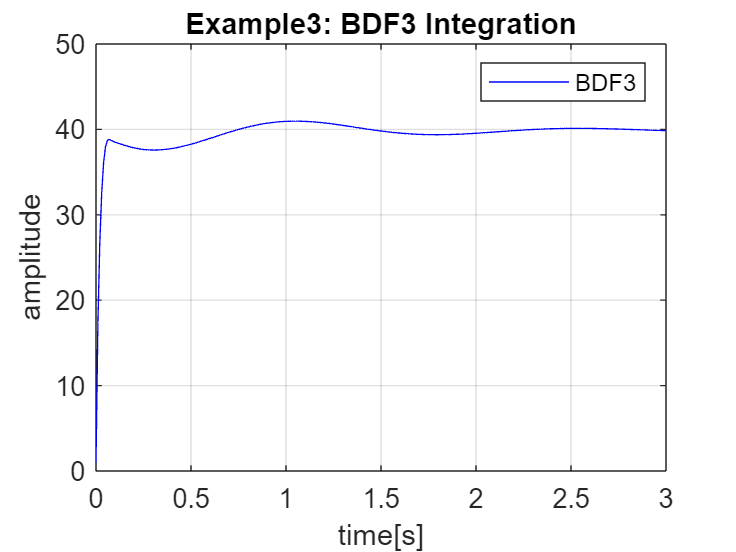

tBDF3 = 0:hBDF3:tend;
yBDF3 = BDF3(A,b,c,d,u,hBDF3,tend,x0); 

plot(tBDF3,yBDF3(2,:),"blue");
title('Example3: BDF3 Integration'); grid on;
ylabel('amplitude'); xlabel('time[s]'); legend('BDF3');